# Parse .hmod Files

Suppose you have hank1.hmod in the working directory. Call in MATLAB

clear_hans
hans hank1

Parsing...ok!
Compiling dpopt_vfi
Building with 'MinGW64 Compiler (C++)'.
MEX completed successfully.


ans = struct with fields:
               parameters: {'beta'  'gamma'  'nu'  'chi'  'w'  'r'  'D'  'tau'}
                var_shock: {'e'  'taxed'}
                var_state: 'b'
              var_pre_vfi: 'budget_n1'
               var_policy: {'c'  'bp'  'n'}
                  var_aux: 'ne'
                  var_agg: {'Y'  'pii'  'w'  'S'  'PA'  'PB'}
            var_agg_shock: {'beta'  'm_shock'}
           var_agg_params: {'G'  'theta'  'pop_taxed'  'phi'  'z'  'ii0'  'mu'  'B'}
           var_agg_assign: {'N'  'D'  'ii'  'r'  'tau'  'pstar'}
    var_agg_in_ind_params: {'w'  'D'  'r'  'tau'  'beta'}
            var_ind_in_eq: {'ne'  'bp'}

As shown, HANS parases the hmod file, compiles the mex files, and returns a structure that describes the model.

clear_hans in the first line clears any cached files generated before.

# Solve the Stationary Equilibrium

Call the generated code solve_cali for calibration

tic;
cali_rslt = solve_cali;

Evaluating at var_agg: 1, 5.6, 
VFI converged (metric_v) 0.00168503, (metric_pol) 0 in 476 iterations
Range of b: 0, 32.3227
Equilbirium residual: -0.0405098, -0.323861, 

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   1.065268e-01   3.263845e-01
Evaluating at var_agg: 1.0001, 5.6, 
VFI converged (metric_v) 8.03659e-05, (metric_pol) 0 in 216 iterations
Range of b: 0, 32.3227
Equilbirium residual: -0.0404013, -0.323684, 
Evaluating at var_agg: 1, 5.60056, 
VFI converged (metric_v) 4.51514e-06, (metric_pol) 0 in 222 iterations
Range of b: 0, 32.3227
Equilbirium residual: -0.0405116, -0.323222, 
Evaluating at var_agg: 1.03796, 5.8252, 
VFI converged (metric_v) 3.06396e-05, (metric_pol) 0 in 386 iterations
Range of b: 0, 31.3304
Equilbirium residual: -4.0175e-06, 0.000127707, 

             1              1              4   1.632513e-08   1.277698e-04   2.283784e-01   1.

fprintf('Time used for calibration at the steady state:\n');toc;

Time used for calibration at the steady state:
Elapsed time is 1.122064 seconds.


cali_rslt.var_agg

ans = struct with fields:
          N: 1.0380
          B: 5.8251
       beta: 0.9860
    m_shock: 0
          Y: 1.0380
          w: 0.8333
          D: 0.1730
          r: 0.0050
        tau: 0.1159
         PA: 6.4111
         PB: 6.4111
          S: 1
        pii: 0

As shown, the function returns a structure that describes the calibrated stationary equilibrium.

# Solve the Linearized Transition Path as a Warmup

We solve a trivial lineraized transition path to obtain the Jacobian matrix of individual aggregates with respect to parameters.

The Jacobian matrix will be reused in solving non-linear transition paths later.

options = struct;
trans_linear_rslt = solve_trans_linear(cali_rslt, options);

# Solve the Transition Path with the Liquidity Shock

The liquidity shock raises the discount factor for all households. In a New-Keynesian framework, this is a negative demand shock that could drive the economy to the zero lower bound.

Let's first generate the liquidity shock that is used in the original paper. $\beta$ is raised by a small percentage points for 33 periods.

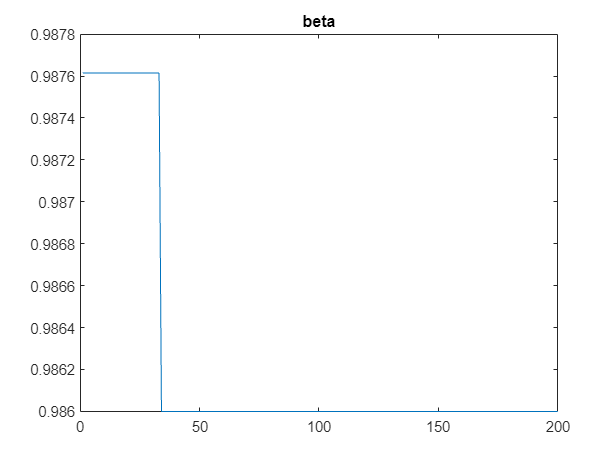

T = 200;
beta_factor = 1.001638;
beta_t = cali_rslt.var_agg.beta*ones(1,T);
beta_t(1:33) = cali_rslt.var_agg.beta * beta_factor;
figure; plot(beta_t); title('beta')

We then pass in the liquidity shock to solve the transition path after the liquidity shock hits.

options = struct;
options.beta_t = beta_t;
options.trans_linear_rslt = trans_linear_rslt;
options.trans_solver = 'Newton';
tic;
trans_nonlinear_rslt_zlb = solve_trans_nonlinear(cali_rslt, cali_rslt, options);

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   4.486206e+00   2.118066e+00

             1              1              2   6.245582e-01   7.902899e-01   4.268511e+00   1.000000e+00         Newton

             2              1              4   8.501378e-02   2.915712e-01   3.329662e+00   1.000000e+00         Newton

             3              1              6   1.200015e-03   3.464123e-02   5.306648e-01   1.000000e+00         Newton

             4              1              8   8.453417e-06   2.907476e-03   5.548852e-02   1.000000e+00         Newton

             5              1             10   1.127025e-07   3.357119e-04   9.155388e-03   1.000000e+00         Newton

             6              1             12   1.286371e-10   1.134183e-05   5.020893e-04   1.000000e+00         Newton


fprintf('Time used for solving the transition path after the liquidty shock:\n');toc;

Time used for solving the transition path after the liquidty shock:
Elapsed time is 2.615578 seconds.


Note that we have reused the Jacobian of individual aggregates with respect to parameters in trans_linear_rslt by passing it to options. We also use a 'Netwon' solver.

We now inspect the transition path. As shown below, indeed the liquidity shock triggers an interest rate zero lower bound, leading to substantial falls in output and inflation.

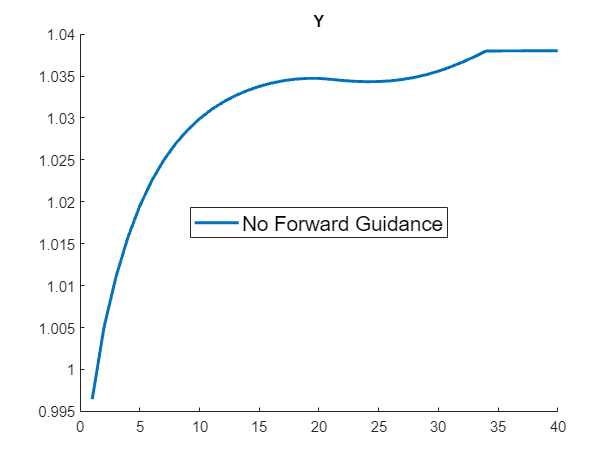

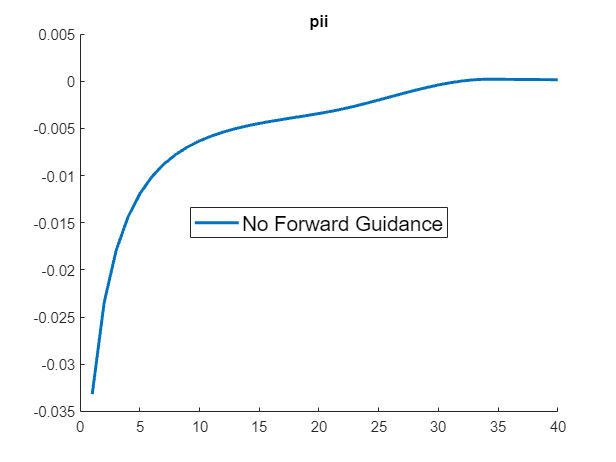

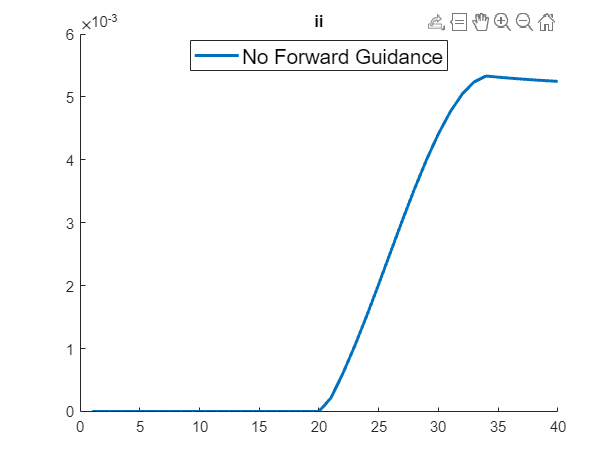

varnames = {'Y','pii','ii'};
for i=1:length(varnames)
    figure; hold on;
    var = varnames{i};
    plot(trans_nonlinear_rslt_zlb.var_agg_t.(var)(1:40),'-','LineWidth',2.0);
    legend({'No Forward Guidance'},'FontSize',14,'Location','Best');
    title(var);
end

# Solve the Transition Path with the Liquidity Shock and Forward Guidance

As shown above, the liquidity shock causes a zero lower bound that lasts for 20 periods.

The forward guidance commits to setting the nominal interest rate at zero for extra three periods. This can be achieved by assigning a very negative Taylor rule shock for the first 23 periods, as the nominal interest rate is bounded below by zero in the definition of equilbirum conditions.

m_shock_t = zeros(1,T);
m_shock_t(1:23) = -100;     % a large number make sure it's pegging
m_shock_t(24) = -0.00092;   % this adjustment follows MNS's original paper

options = struct;
options.beta_t = beta_t;
options.m_shock_t = m_shock_t;
options.trans_linear_rslt = trans_linear_rslt;
options.HANS_x = trans_nonlinear_rslt_zlb.HANS_x;
options.trans_solver = 'Newton';
trans_nonlinear_rslt_zlb_and_fg = solve_trans_nonlinear(cali_rslt, cali_rslt, options);

     Iteration    Line Search     Func-count    ||f(x)||^2     fnorm(x)      Norm of Step      Step Size      Algorithm

             0              0              1   1.690161e-02   1.300062e-01

             1              1              2   1.548295e-02   1.244305e-01   1.815699e+00   1.000000e+00         Newton

             2              1              4   9.094189e-06   3.015657e-03   2.100678e-01   1.000000e+00         Newton

             3              1              6   9.868972e-06   3.141492e-03   3.518881e-02   1.000000e+00         Newton

             3              2              7   7.076167e-07   8.411996e-04   1.759440e-02   5.000000e-01         Newton

             4              1              9   1.264677e-06   1.124578e-03   2.507298e-03   1.000000e+00         Newton

             4              2             10   6.810113e-07   8.252341e-04   1.253649e-03   5.000000e-01         Newton

             5              1             12   1.165918e-07   3.414554e-04   

Note that we pass in the previously solved transition path, HANS_x, into options as a warm-up for solving the model with forward guidance. This is not necessary but can solve the model faster.

We next compare the the transition paths with and without forward guidance. This replicates Figures 7-9 in their paper.

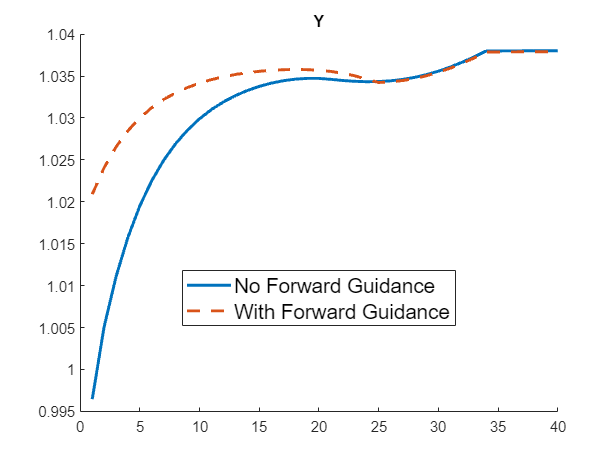

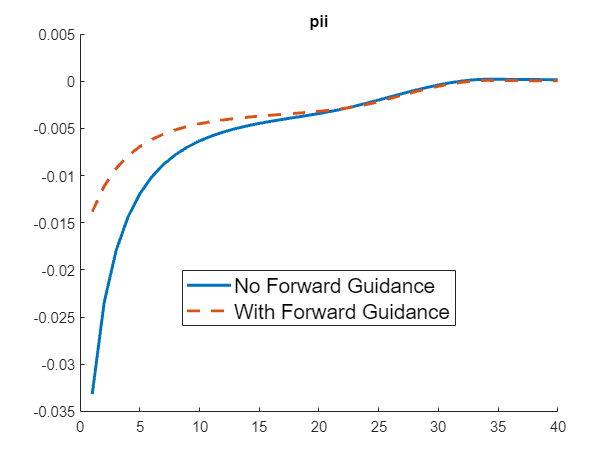

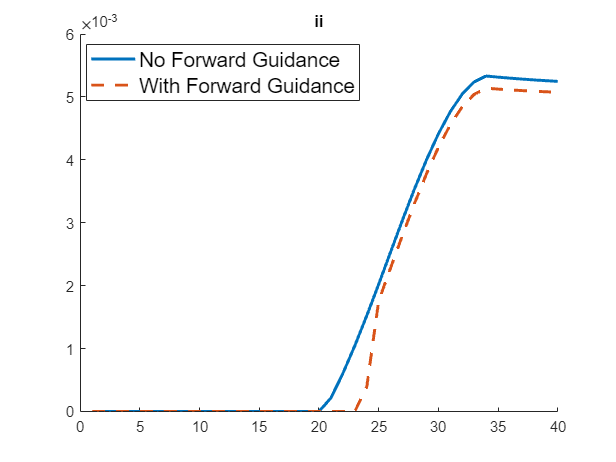

varnames = {'Y','pii','ii'};
for i=1:length(varnames)
    figure; hold on;
    var = varnames{i};
    plot(trans_nonlinear_rslt_zlb.var_agg_t.(var)(1:40),'-','LineWidth',2.0);
    plot(trans_nonlinear_rslt_zlb_and_fg.var_agg_t.(var)(1:40),'--','LineWidth',2.0);
    legend({'No Forward Guidance','With Forward Guidance'},'FontSize',14,'Location','Best');
    title(var);
end